clear; clc; close all;
addpath ..\
basepath = '.\data\';

%% read RINEX files
gnav = gt.Gnav([basepath 'base.nav']);
gobs = gt.Gobs([basepath 'base_1Hz_100s.obs']);

% compute satellite position
disp('compute satellite position...');

compute satellite position...


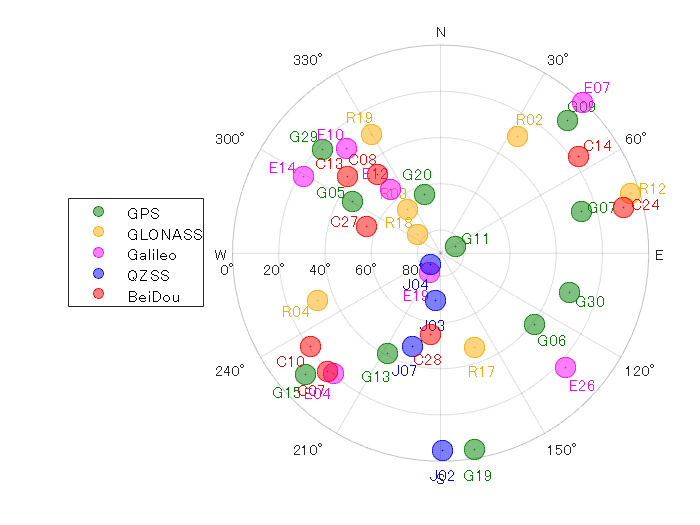

gsat = gt.Gsat(gobs, gnav, gt.C.EPHOPT_BRDC);

% compute satellite azimath and elevation angles
gsat.setRcvPos(gobs.pos); % RINEX header positon

% plot
gsat.plotSky(1);